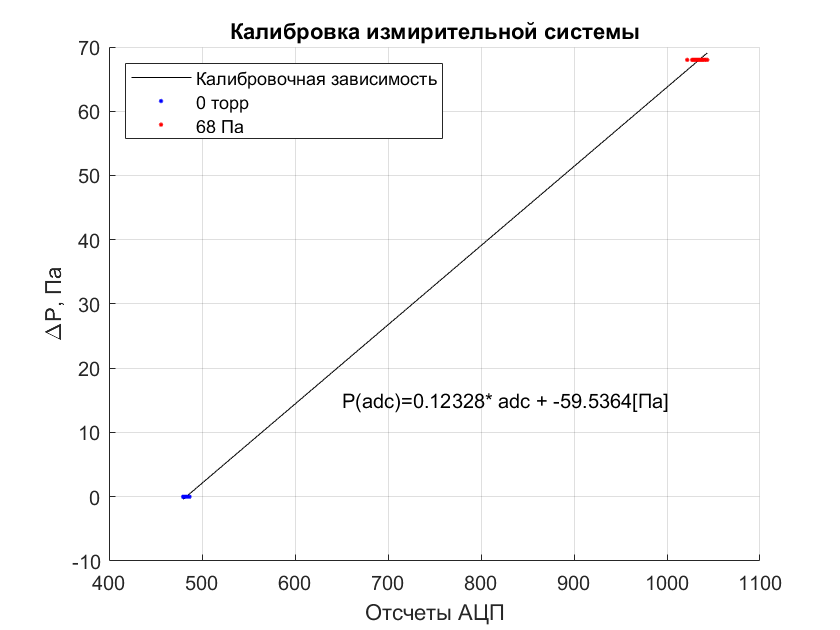

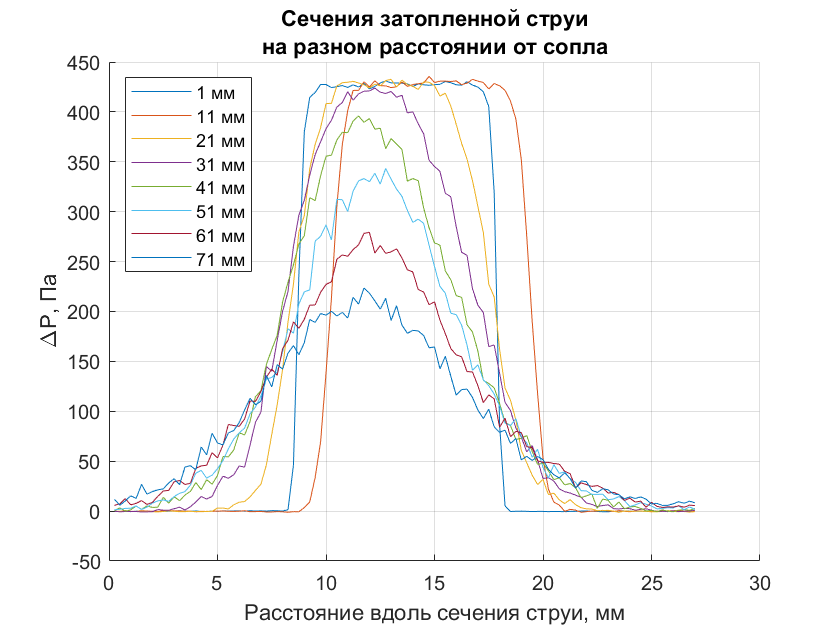

callib = load("Desktop/Study/MIPT/5. GET/6. Labs/Lab 2. Измерение расхода затопленной струи/jet/2-experimentData/calib.dat");
callibr_zero = load("Desktop/Study/MIPT/5. GET/6. Labs/Lab 2. Измерение расхода затопленной струи/jet/2-experimentData/calibzero.dat");
mm01 = load ("Desktop/Study/MIPT/5. GET/6. Labs/Lab 2. Измерение расхода затопленной струи/jet/2-experimentData/01mm.dat");
mm11 = load("Desktop/Study/MIPT/5. GET/6. Labs/Lab 2. Измерение расхода затопленной струи/jet/2-experimentData/11mm.dat");
mm21 = load("Desktop/Study/MIPT/5. GET/6. Labs/Lab 2. Измерение расхода затопленной струи/jet/2-experimentData/21mm.dat");
mm31 = load("Desktop/Study/MIPT/5. GET/6. Labs/Lab 2. Измерение расхода затопленной струи/jet/2-experimentData/31mm.dat");
mm41 = load("Desktop/Study/MIPT/5. GET/6. Labs/Lab 2. Измерение расхода затопленной струи/jet/2-experimentData/41mm.dat");
mm51 = load("Desktop/Study/MIPT/5. GET/6. Labs/Lab 2. Измерение расхода затопленной струи/jet/2-experimentData/51mm.dat");
mm61 = load("Desktop/Study/MIPT/5. GET/6. Labs/Lab 2. Измерение расхода затопленной струи/jet/2-experimentData/61mm.dat");
mm71 = load("Desktop/Study/MIPT/5. GET/6. Labs/Lab 2. Измерение расхода затопленной струи/jet/2-experimentData/71mm.dat");
adc_1 = callib (:, 2);
adc_2 = callibr_zero (:, 2);
p1 = ones(length(adc_1),1)*68;
p2 = ones(length(adc_2),1)*0;
Adc_c = [adc_1; adc_2];
P_c = [p1; p2];
c = polyfit(Adc_c, P_c, 1);
callibrFigure = figure ('Name','Калибровка', "NumberTitle","off");
hold all;
plot(Adc_c, polyval(c, Adc_c),'k-');
plot(adc_2, p2, 'b.');
plot(adc_1, p1, 'r.');
grid on;
xlabel('Отсчеты АЦП');
ylabel('\DeltaP, Па');
legend('Калибровочная зависимость','0 торр','68 Па', 'Location',"northwest");
title('Калибровка измирительной системы');
text(650, 15,['P(adc)=', num2str(c(1)), '* adc + ', num2str(c(2)), '[Па]']);
%%set(gcf, "Visible", "on")
dx = 0.25;
x = mm01(:, 1)'*0.25;
p01 = polyval(c , mm01(:,2));
p11 = polyval(c , mm11(:,2));
p21 = polyval(c , mm21(:,2));
p31 = polyval(c , mm31(:,2));
p41 = polyval(c , mm41(:,2));
p51 = polyval(c , mm51(:,2));
p61 = polyval(c , mm61(:,2));
p71 = polyval(c , mm71(:,2));
pressure = [p01, p11, p21, p31, p41, p51, p61, p71];
zNames = {'1 мм'; '11 мм'; '21 мм'; '31 мм'; '41 мм'; '51 мм'; '61 мм';'71 мм'};
z = [1, 11, 21,31,41,51, 61, 71];
f2 = figure ('Name','Калибровка      ', "NumberTitle","off"); 
hold on;
grid on; 
title({'Сечения затопленной струи', 'на разном расстоянии от сопла'});
xlabel('Расстояние вдоль сечения струи, мм');
ylabel('\DeltaP, Па');
for i = 1:size (pressure, 2)
    plot(x, pressure(:, i), "DisplayName", zNames{i});
end
legend('Location','northwest');
saveas(f2, 'pressure.png');

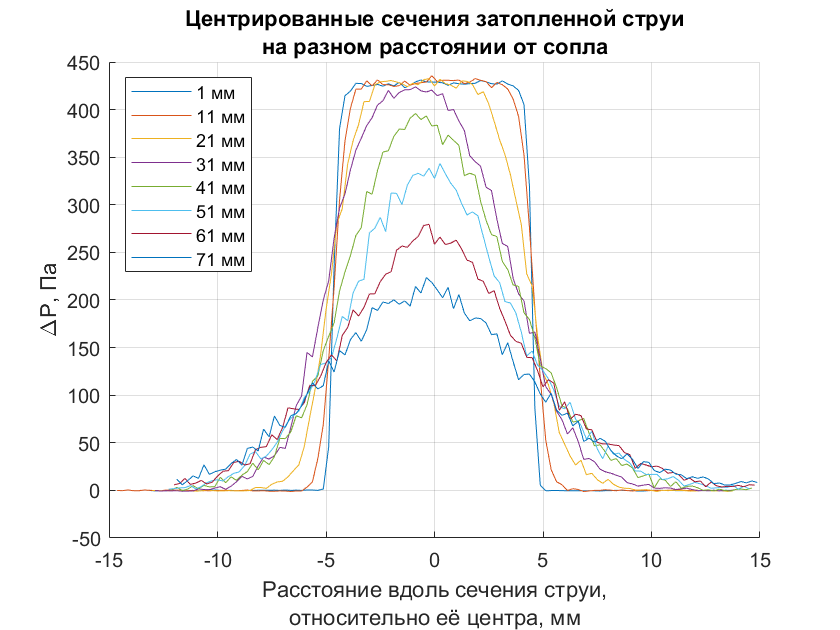

%set(gcf, "Visible", "on");
f3 = figure('Name','Калибровка      ', "NumberTitle","off");
hold on ;
grid on;
title({'Центрированные сечения затопленной струи', 'на разном расстоянии от сопла'});
xlabel({'Расстояние вдоль сечения струи,','относительно её центра, мм'});
ylabel('\DeltaP, Па');
xCentred = zeros(size(pressure));
offset = 50;
for i = 1:size(pressure, 2)
    right = x(find(pressure(:, i) > offset, 1, 'last'));
    left = x(find(pressure(:, i) > offset, 1));
    center = left + (right - left)/2 ;
    xCentred(:, i) = x - center;
    plot(xCentred(:, i), pressure(:,i), 'DisplayName', zNames{i});
end
legend('Location','northwest');
saveas(f3, 'centered_pressure.png');
%set(gcf, "Visible", "on");
hold off;

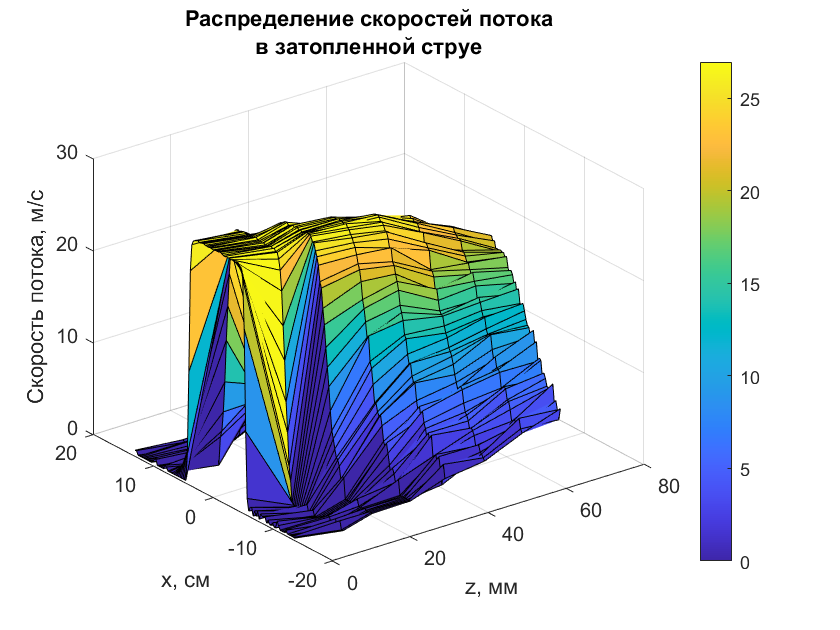

U=ones(2, size(pressure,1),size(z,2));
for j=1:size(z,2)
    for i=1:size(pressure,1)
        U(1,i,j)=xCentred(i,j);
        U(2,i,j)=0;
        if(pressure(i,j)>0)
            U(2,i,j)=sqrt((2*pressure(i,j)/1.2));
        end
    end
end
f4=figure();
Oz=ones(size(z,2),size(pressure, 1));
Oy=ones(size(z,2),size(pressure, 1));
for j=1:size(z,2)
    for i=1:size(pressure, 1)
        Oz(j,i)=z(1,j);
        Oy(j,i)=U(2,i,j);
    end
end
surf(Oz,xCentred',Oy);
colorbar;
ylabel("x, cм");
xlabel("z, мм");
zlabel("Скорость потока, м/с");
title({'Распределение скоростей потока', 'в затопленной струе'});
%set(gcf, "Visible", "on");
saveas(f4, 'velocity.png');

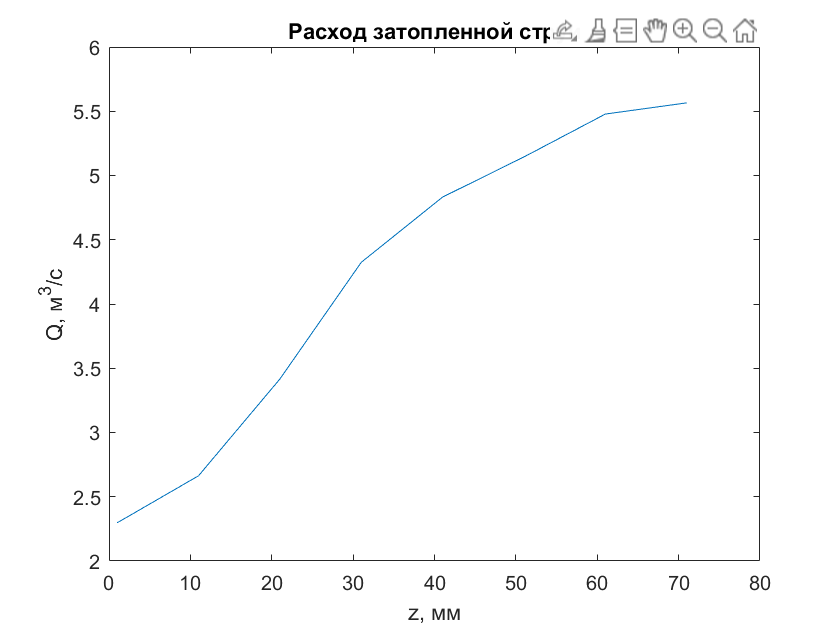

f5=figure();
Q=zeros(size(z));
for j=1:size(z,2)
    for i=1:size(x,2)
        Q(j)=(Q(j)+((U(2,i,j)*abs(U(1,i,j))))*dx/2000);
    end
    Q(j)=Q(j)*pi*2*1.2;
end
plot(z,Q);
set(gcf, "Visible", "on");
title('Расход затопленной струи');
xlabel('z, мм');
ylabel('Q, м^3/c');
saveas(f5, 'Q.png');